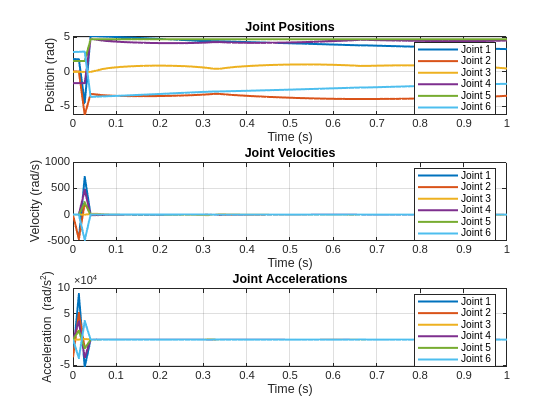

close all;
clc;

% Load UR5e robot
robot = loadrobot("universalUR5e");
robot.DataFormat = 'row';

% Add gripper (optional)
ur5e = exampleHelperAddGripper(robot);

% Home position
homePosition = deg2rad([-15, -126, 113, -80, -91, 76]);
for i = 1:6
    ur5e.Bodies{i+2}.Joint.HomePosition = homePosition(i);
end

% Inverse kinematics solver
ik = inverseKinematics('RigidBodyTree', ur5e);
weights = [1, 1, 1, 1, 1, 1];
initialGuess = homePosition;

% Define waypoints
waypoints = [ -0.4, 0.4, 0.7, 0.9;  % X positions
              0.9, 0.8, 0.4, 0.0;   % Y positions
              0.2, 0.4, 0.0, 0.2];  % Z positions

% Number of samples per segment
numSamplesPerSegment = 25;

% Initialize variables for storing interpolated points and configurations
interpolatedPoints = [];
interpolatedConfigs = [];

% Interpolate between each pair of waypoints
for i = 1:size(waypoints, 2)-1
    % Linear interpolation between two waypoints
    t = linspace(0, 1, numSamplesPerSegment);
    segmentPoints = (1 - t)' * waypoints(:, i)' + t' * waypoints(:, i+1)';
    interpolatedPoints = [interpolatedPoints; segmentPoints]; % Append to the total points
    
    % Compute IK for the segment
    for j = 1:size(segmentPoints, 1)
        T = trvec2tform(segmentPoints(j, :));  % Convert to homogeneous transformation
        [theta, ~] = ik('tool0', T, weights, initialGuess);
        interpolatedConfigs = [interpolatedConfigs; theta];
        initialGuess = theta;  % Update initial guess for the next step
    end
end

% Time vector (uniformly spaced for all points)
time = linspace(0, 1, size(interpolatedPoints, 1));

% Compute joint positions, velocities, and accelerations
jointPositions = interpolatedConfigs; % Positions are the configurations
jointVelocities = diff(jointPositions) ./ diff(time'); % Approximate velocities
jointAccelerations = diff(jointVelocities) ./ diff(time(1:end-1)'); % Approximate accelerations

% Add zeros for alignment with time vector (since diff reduces length)
jointVelocities = [jointVelocities; zeros(1, size(jointVelocities, 2))];
jointAccelerations = [jointAccelerations; zeros(2, size(jointAccelerations, 2))];

% Plot positions, velocities, and accelerations for each joint
figure;
for joint = 1:size(jointPositions, 2)
    subplot(3, 1, 1); % Joint positions
    plot(time, jointPositions(:, joint), 'LineWidth', 1.5);
    hold on;
    title('Joint Positions');
    xlabel('Time (s)');
    ylabel('Position (rad)');
    grid on;

    subplot(3, 1, 2); % Joint velocities
    plot(time, jointVelocities(:, joint), 'LineWidth', 1.5);
    hold on;
    title('Joint Velocities');
    xlabel('Time (s)');
    ylabel('Velocity (rad/s)');
    grid on;

    subplot(3, 1, 3); % Joint accelerations
    plot(time, jointAccelerations(:, joint), 'LineWidth', 1.5);
    hold on;
    title('Joint Accelerations');
    xlabel('Time (s)');
    ylabel('Acceleration (rad/s^2)');
    grid on;
end

% Add legends after all plots are drawn
subplot(3, 1, 1); legend("Joint 1", "Joint 2", "Joint 3", "Joint 4", "Joint 5", "Joint 6");
subplot(3, 1, 2); legend("Joint 1", "Joint 2", "Joint 3", "Joint 4", "Joint 5", "Joint 6");
subplot(3, 1, 3); legend("Joint 1", "Joint 2", "Joint 3", "Joint 4", "Joint 5", "Joint 6");


% Visualize the robot's path
figure;
show(ur5e, homePosition, 'Frames', 'on', 'PreservePlot', true);
hold on;

% Plot interpolated trajectory
plot3(interpolatedPoints(:, 1), interpolatedPoints(:, 2), interpolatedPoints(:, 3), 'r-', 'LineWidth', 2);

plot3(waypoints(1,:), waypoints(2,:), waypoints(3,:), 'bo', 'MarkerFaceColor', 'b');

% Animate the robot motion
for i = 1:size(interpolatedConfigs, 1)
    show(ur5e, interpolatedConfigs(i, :), 'Frames', 'on', 'PreservePlot', false);
    pause(0.1); % Adjust for smooth animation
end


grid on;
axis equal;
view(3);
